# Tutorial 2: Loading and Creating Trajectories in CASPR

This tutorial shows how to load trajectories from XML files and also create trajectories in scripts.

## Load the robot

Load a robot as shown in `T1_load_robot.mlx `

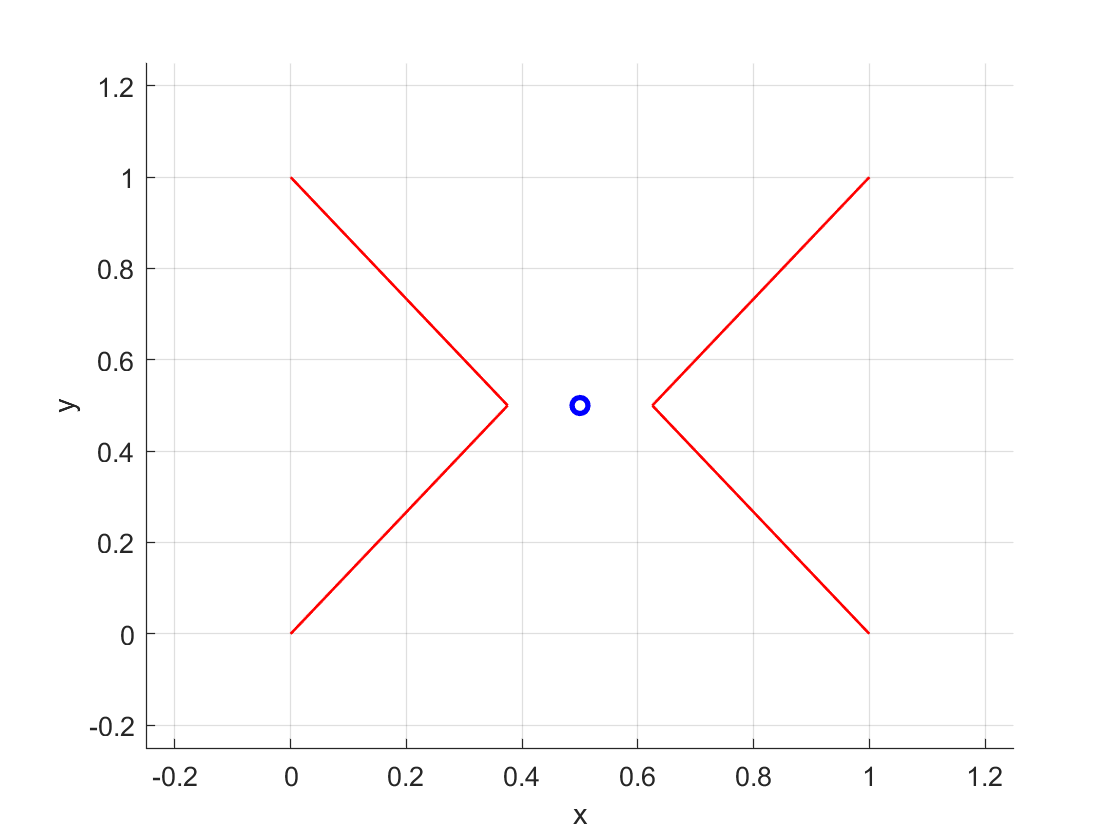

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

## Loading a trajectory through XML trajectory file

Trajectories of predefined types, such as linear, cubic or quintic etc., can be defined within the trajectory XML file

trajectory_linear = model_config.getJointTrajectory('example_linear');

Within the XML file a linear trajectory can be defined as

- `<linear_spline_trajectory id="example_linear" time_definition="absolute" time_step="0.01">`

- `  <points>`

- `    <point>`

- `      <q>0.3 0.5 0.0</q>`

- `    </point>`

- `    <point time="5.0">`

- `      <q>0.7 0.5 0.0</q>`

- `    </point>`

- `  </points>`

- `</linear_spline_trajectory>`

The trajectory can be plotted through the `plotJointPose()` function

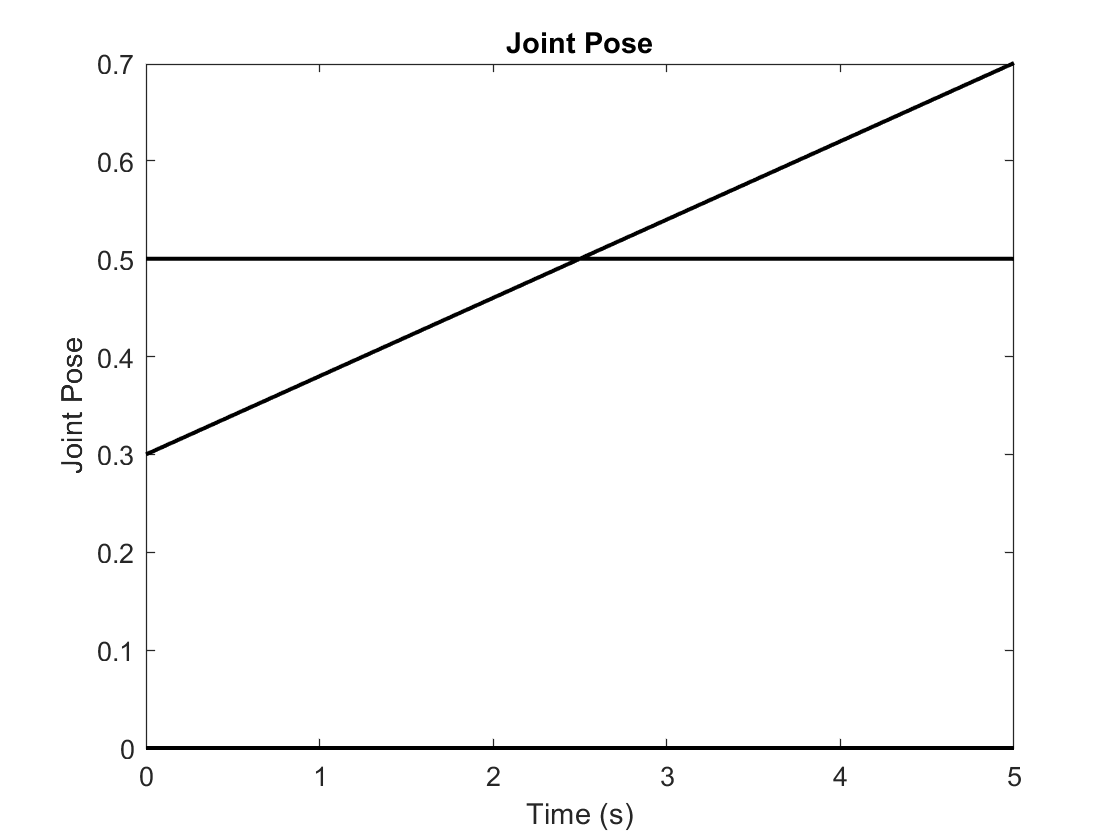

trajectory_linear.plotJointPose();

The set of trajectory names can be seen within the XML file or also within the property

joint_trajectory_names = model_config.jointTrajectoryNamesList

joint_trajectory_names = 1×13 cell array
    {'example_linear'}    {'example_cubic'}    {'example_quintic'}    {'example_infeasible'}    {'example_cubic_average_velocity'}    {'example_parabolic_blend'}    {'example_file'}    {'example_inside'}    {'setpoint_eMPC_infeasible'}    {'example_outside1'}    {'example_outside1_alt'}    {'example_outside2'}    {'example_outside3'}


Another trajectory can be loaded in a similar manner

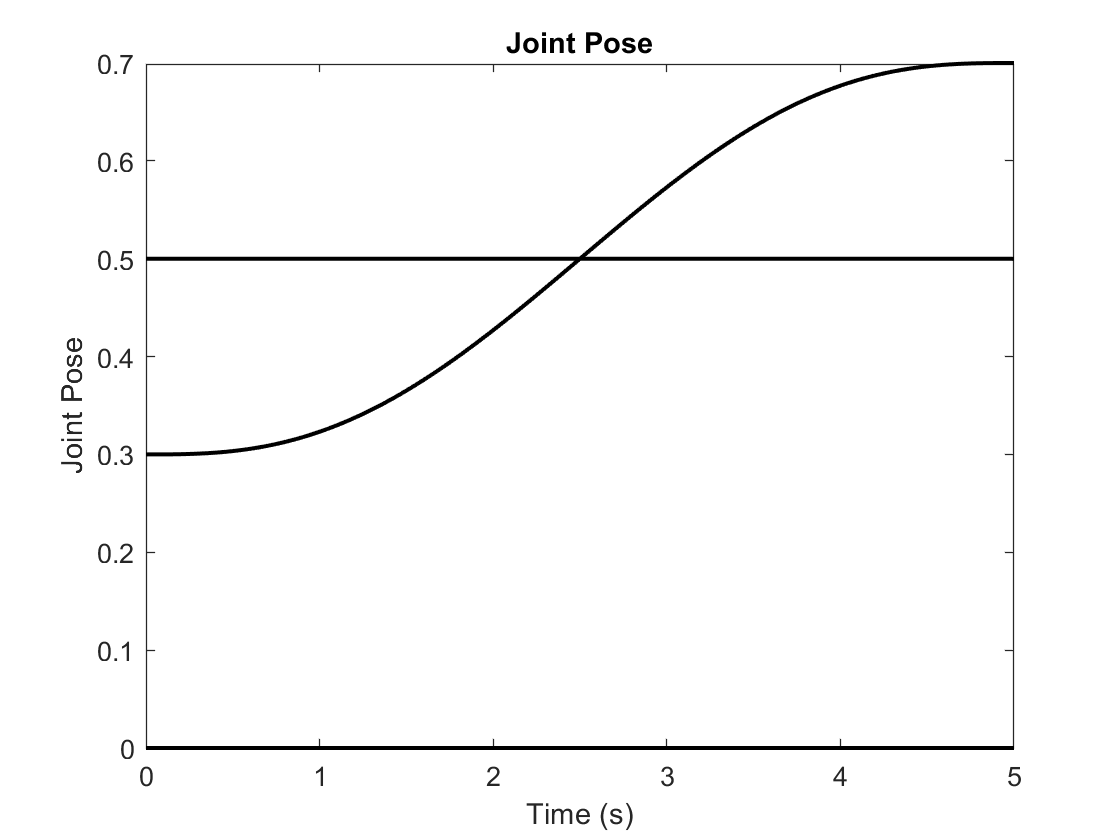

trajectory_quintic = model_config.getJointTrajectory('example_quintic');
trajectory_quintic.plotJointPose();

## Plotting trajectories

In addition to plotting the joint space position, the velocity and acceleration can also be plotted

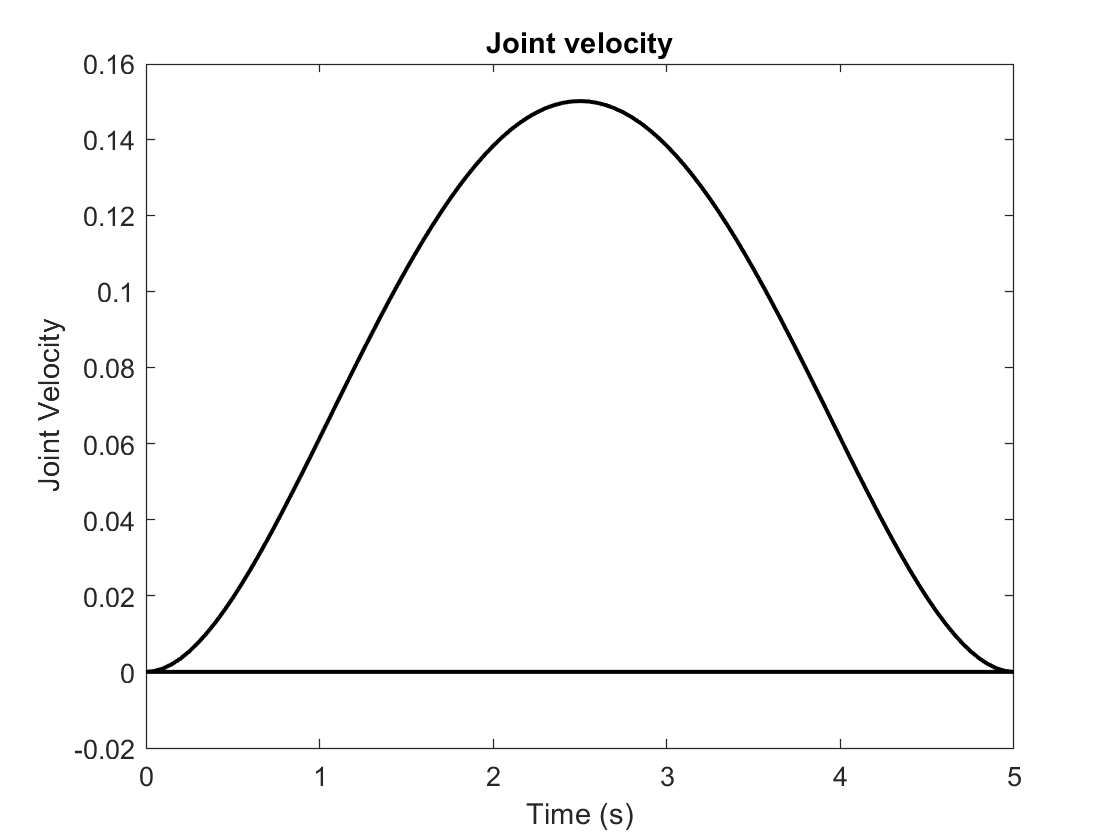

trajectory_quintic.plotJointVelocity();

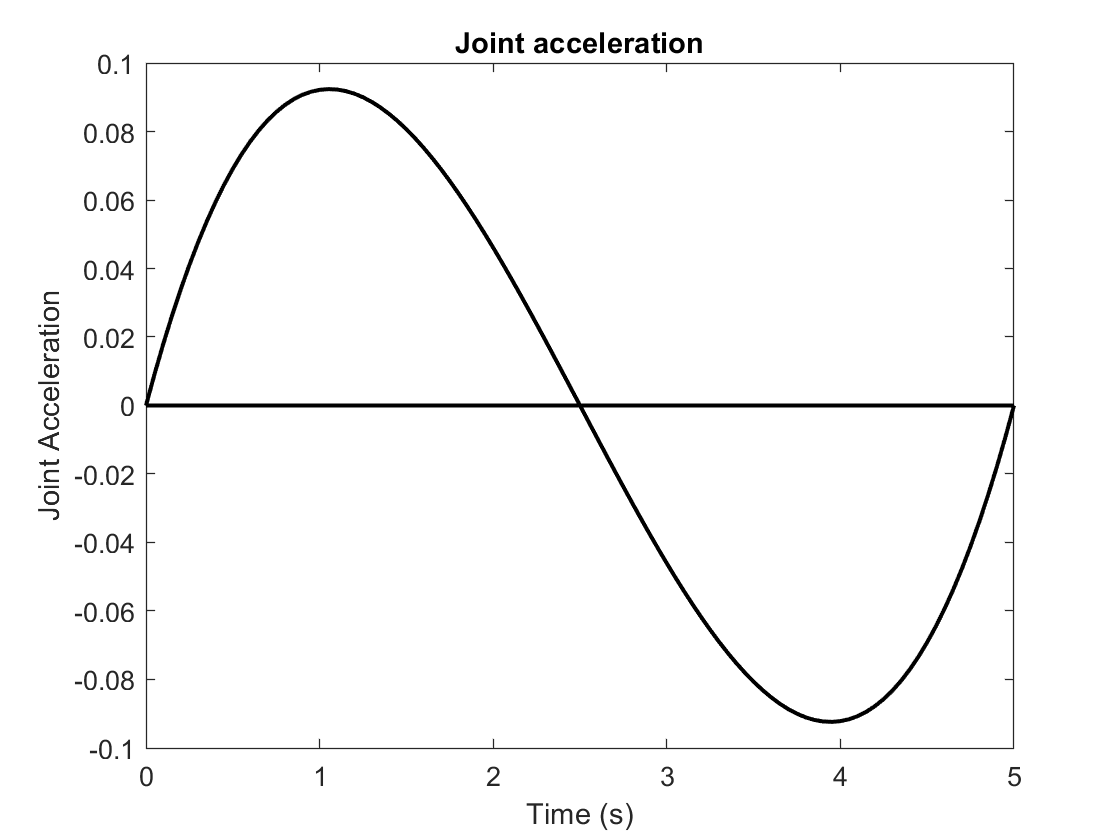

trajectory_quintic.plotJointAcceleration();

Aside from plotting all joint variables simultaneously, one or more joint variables can be independently plotted

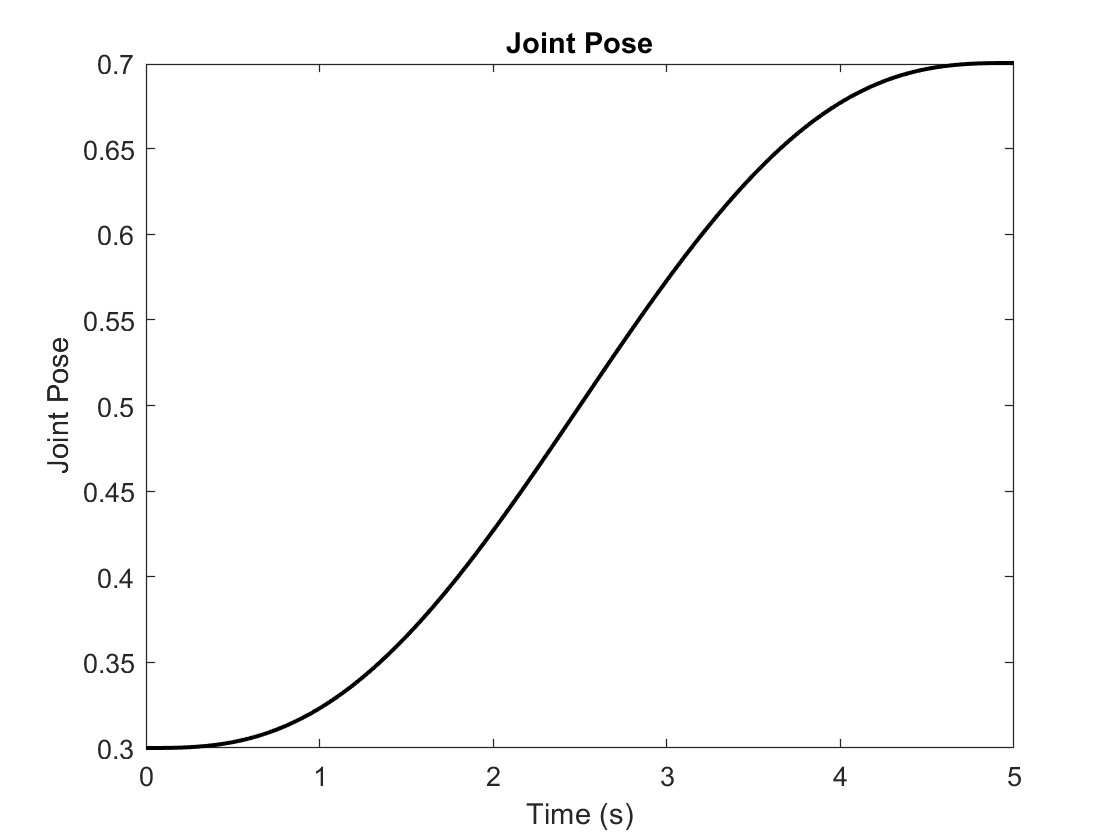

vars_to_plot = [1]; % Array of indices of variables to plot
trajectory_quintic.plotJointPose(vars_to_plot);

## Loading a trajectory through .traj files

Another way to load trajectories more generically is to store trajectories within a text file in the form of 

- `time_step,0.010000`

- `q,0.800000,0.500000,0.100000,v,-0.000000,0.942478,0.000000,a,-2.960881,-0.000000,0.000000`

- `q,0.799852,0.509423,0.100000,v,-0.029604,0.942013,0.000000,a,-2.959420,-0.093004,0.000000 `

- `...`

The file trajectory can then be defined within the XML as

`<file_trajectory id="example_file" filename="example_planar_XY_trajectory_file_example.traj" />`

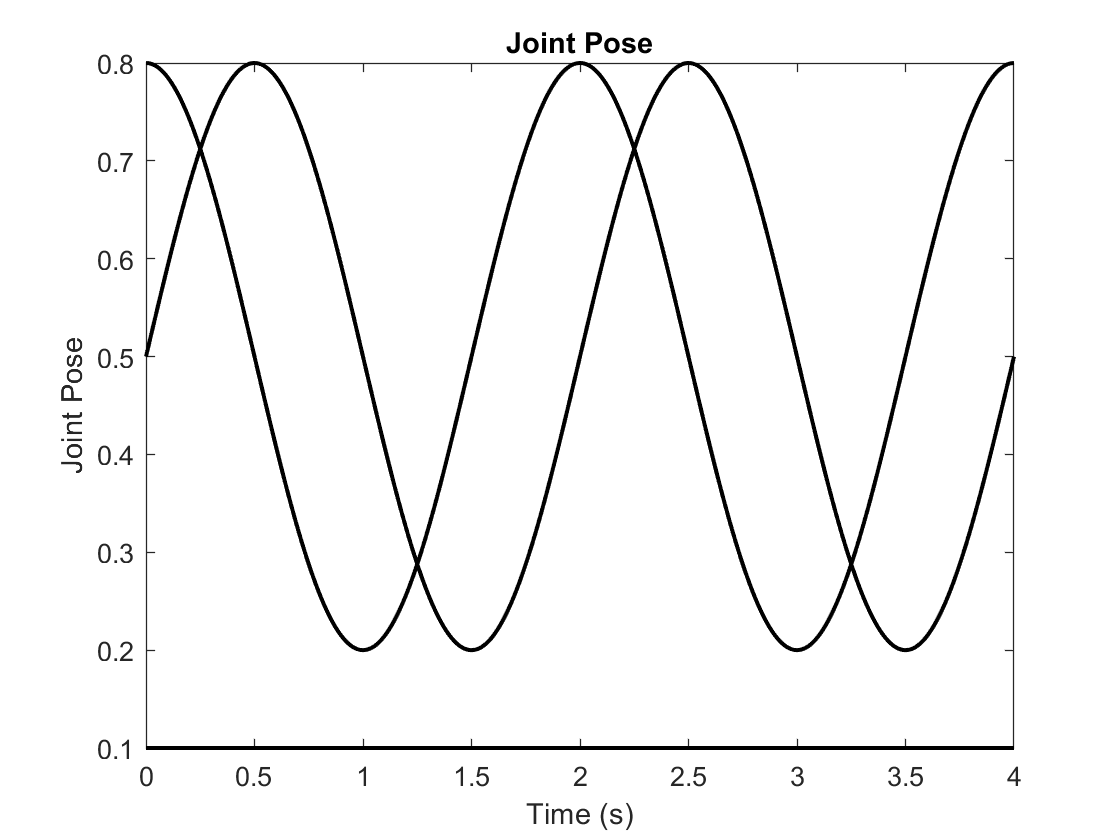

trajectory_file = model_config.getJointTrajectory('example_file');
trajectory_file.plotJointPose();

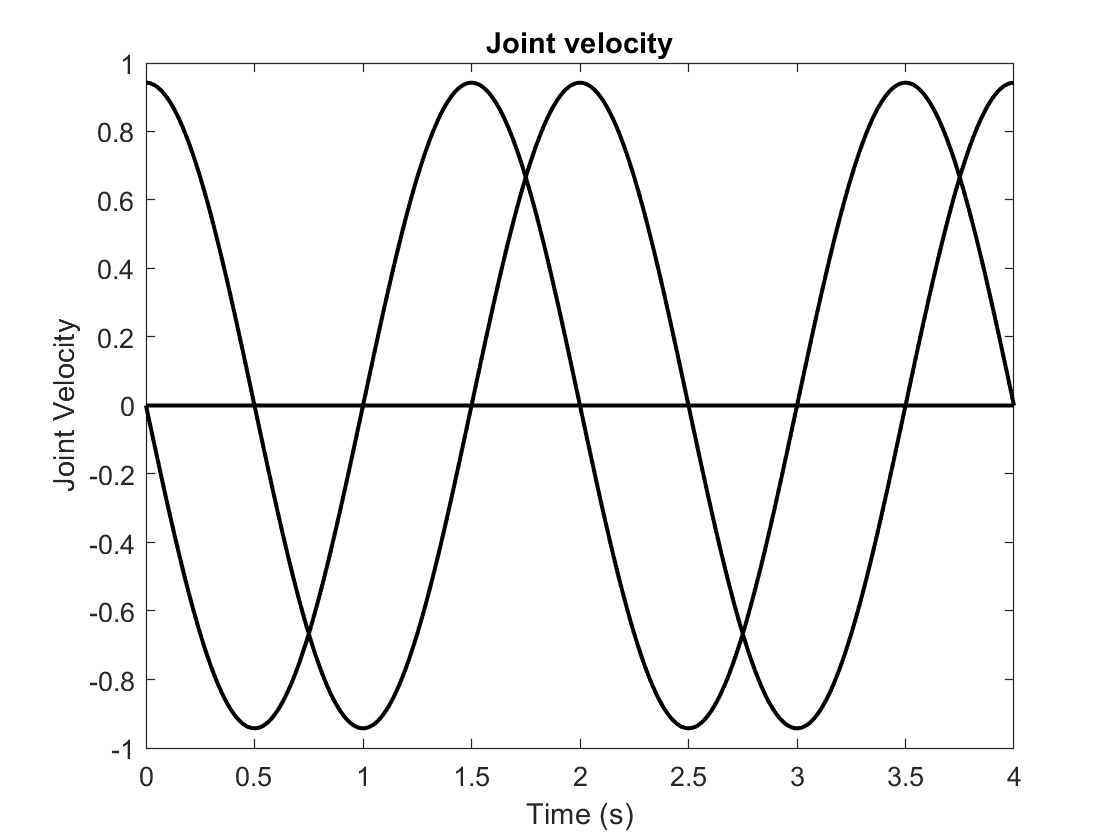

trajectory_file.plotJointVelocity();

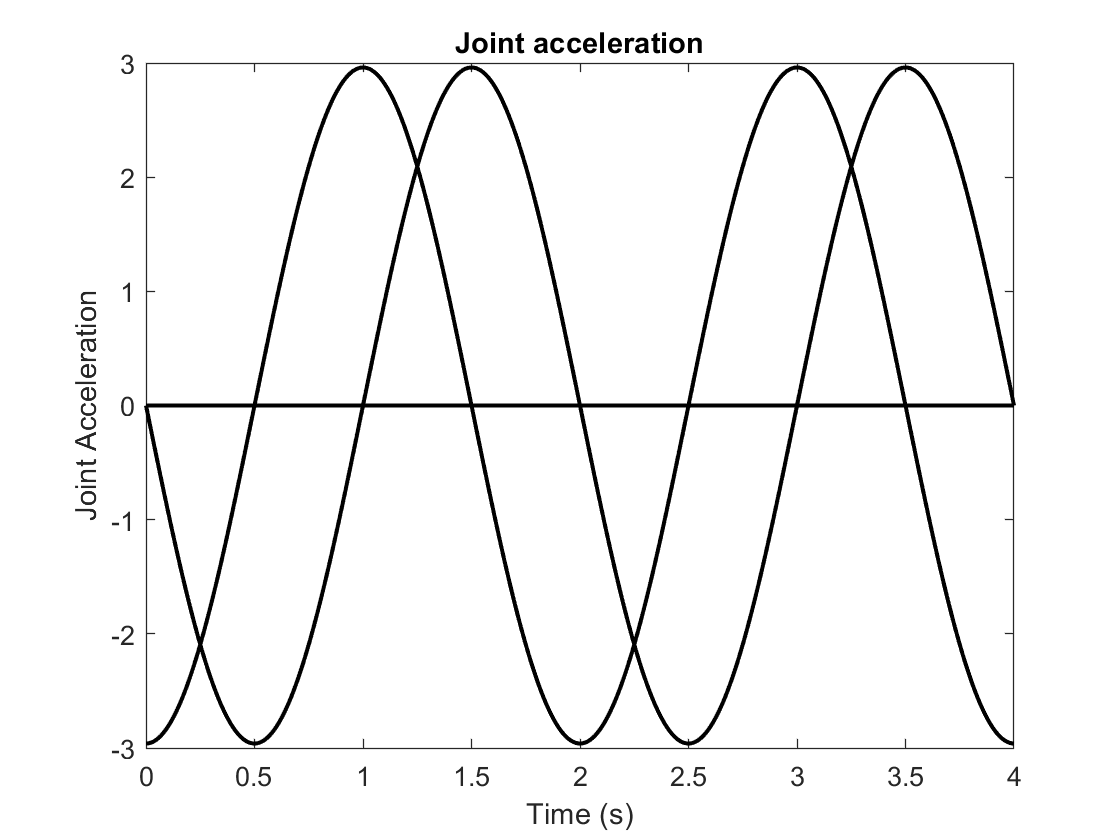

trajectory_file.plotJointAcceleration();

## Saving trajectories

Trajectories that have been created can also be saved using `saveJointTrajectoryFile(file_path)`, for example` trajectory_quintic.saveJointTrajectoryFile('C:\test_quintic.traj')`

## Creating trajectories in code

In addition to specifying trajectories in XML files with the predefined formats, or in a file, users can also dynamically create trajectories using a for-loop in code according any functional form:

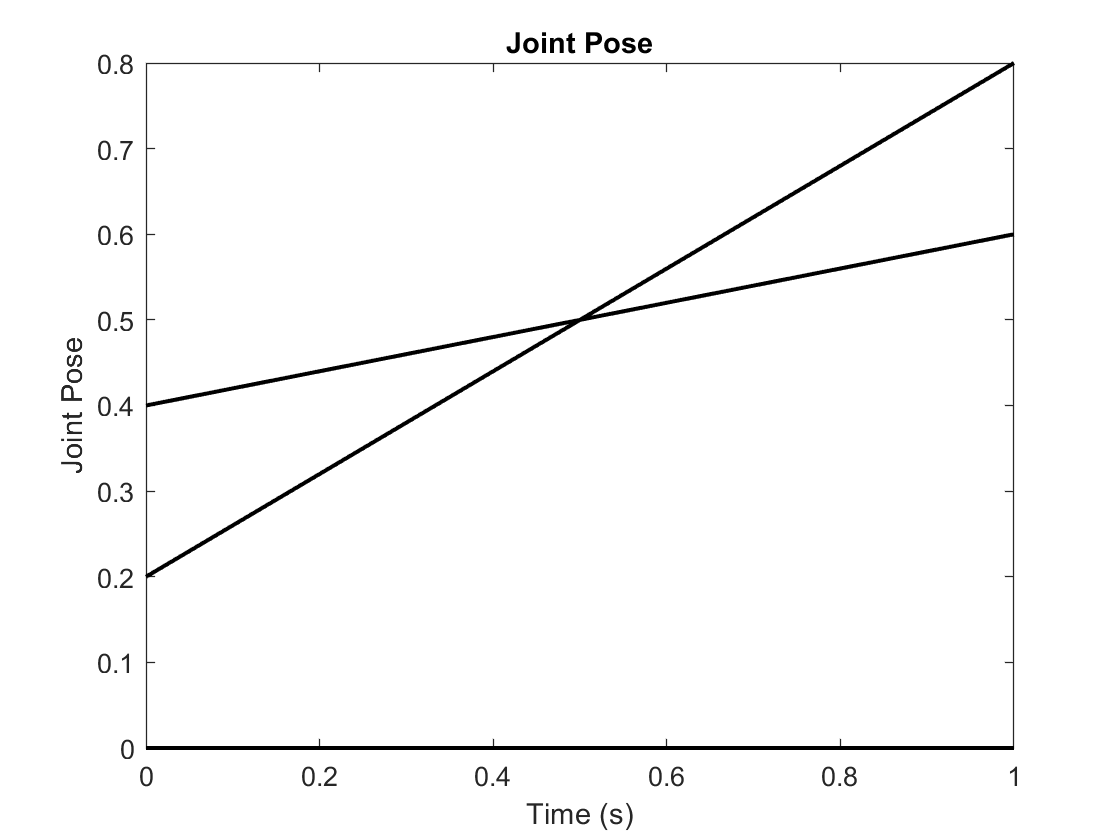

traj_code = JointTrajectory();
traj_code.timeVector = 0:0.01:1.0;
traj_code.q = cell(1, length(traj_code.timeVector));
traj_code.q_dot = cell(1, length(traj_code.timeVector));
traj_code.q_ddot = cell(1, length(traj_code.timeVector));
for i=1:length(traj_code.timeVector)
    % Generate a linear trajectory for x = 0.2 to 0.8, y = 0.4 to 0.6 and
    % theta = 0 to 0 in 1 second
    x = 0.2 + 0.6*traj_code.timeVector(i);
    y = 0.4 + 0.2*traj_code.timeVector(i);
    th = 0;
    traj_code.q{i} = [x; y; th];
    traj_code.q_dot{i} = [0.6; 0.2; 0];
    traj_code.q_ddot{i} = [0; 0; 0];
end
traj_code.plotJointPose();

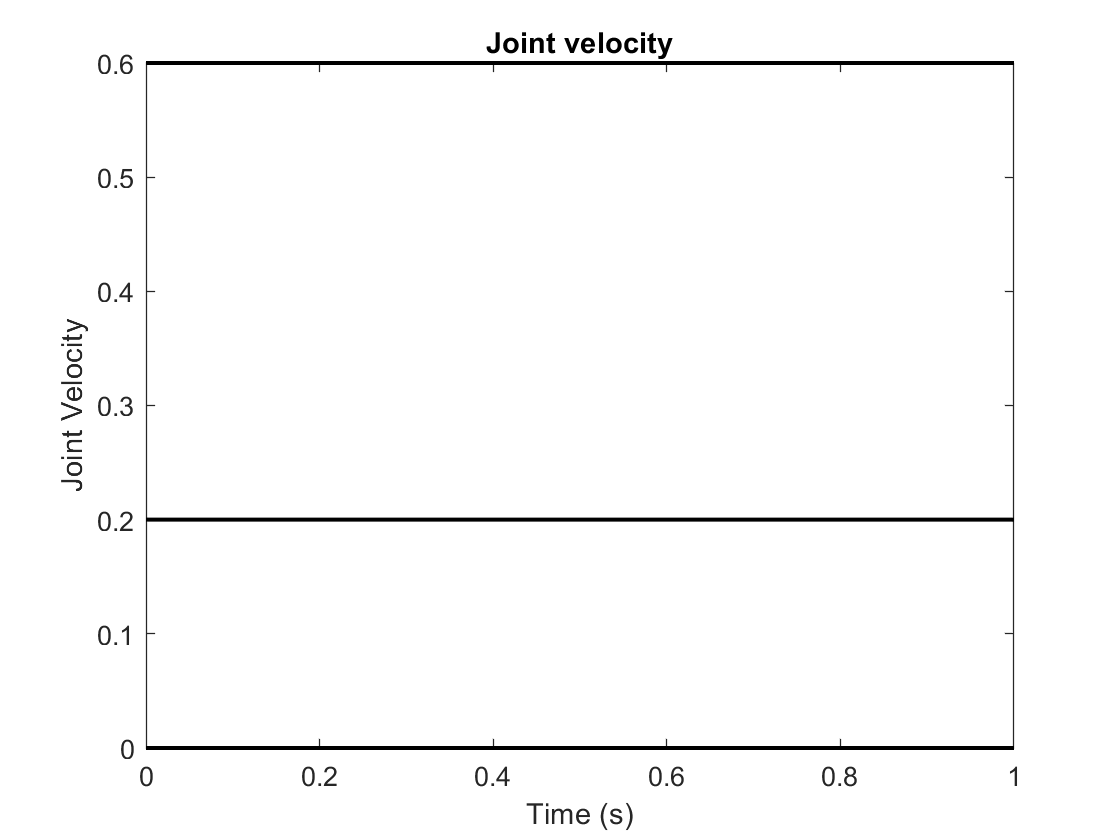

traj_code.plotJointVelocity();

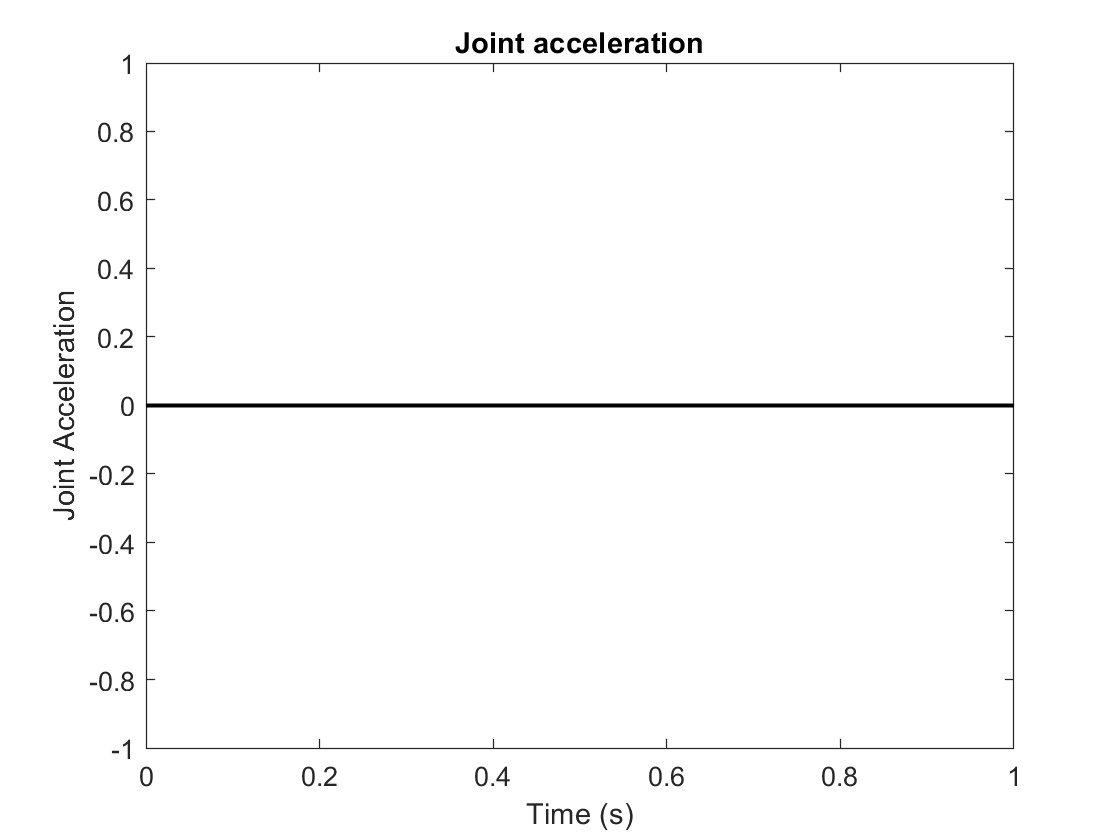

traj_code.plotJointAcceleration();